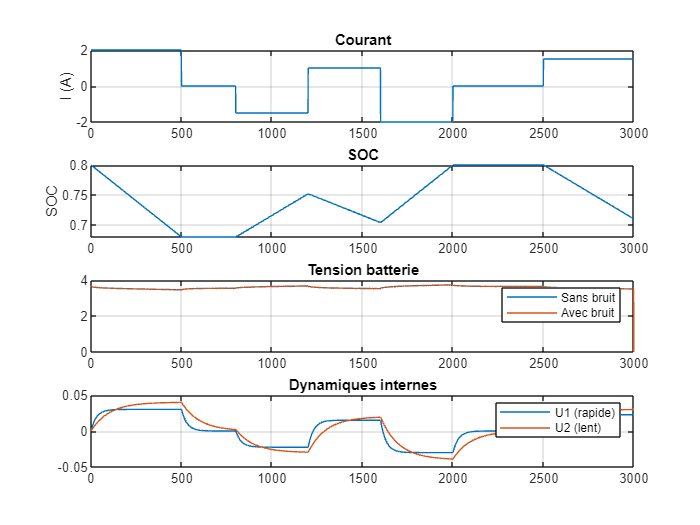

clear; clc; close all;


Q  = 8280;      % capacité de notre battrie (C)

R0 = 0.01;               % Le modele RC choisie (2 eme ordre)
R1 = 0.015; C1 = 2000;
R2 = 0.02;  C2 = 5000;

Ts = 1;        %Temps d'echantillonnage                     

%Discretisation du syst
alpha1 = exp(-Ts/(R1*C1));    
alpha2 = exp(-Ts/(R2*C2));

beta1 = R1*(1 - alpha1);
beta2 = R2*(1 - alpha2);
%Simulation du courant (Charge et Decharge)
N = 3000;
t = (0:N-1)*Ts;        

I = zeros(1,N);

I(1:500)    = 2;      % décharge
I(501:800)  = 0;      % repos
I(801:1200) = -1.5;   % charge
I(1201:1600)= 1;
I(1601:2000)= -2;
I(2001:2500)= 0;
I(2501:end) = 1.5;

%simulation du syst (second ordre)
SOC = zeros(1,N);    %Initialisation des variables d'etats a 0
U1  = zeros(1,N);
U2  = zeros(1,N);
Ut  = zeros(1,N);

SOC(1) = 0.8;          % On suppose le state of charge=0.8(80%) au debut.

for k = 1:N-1
    
    % SOC
    SOC(k+1) = SOC(k) - (Ts/Q)*I(k);     %Calcul du SOC (SOC reel)   
    
    % dynamiques RC
    U1(k+1) = alpha1*U1(k) + beta1*I(k);      %Dynamique rapide
    U2(k+1) = alpha2*U2(k) + beta2*I(k);       %Dynamique lente
    
    % VOC   Tension a vide
    Voc = 3.0 + 0.8*SOC(k); 
    
  % tension batterie en enleve les effets dynamiques (U1, U2) et les chutes
  % de tensions(R0*I)
    Ut(k) = Voc - R0*I(k) - U1(k) - U2(k);    
end

%On ajoute du bruit pour le courant et la tension (On pourra eventuellement
%les modifier pour estimer l'effet du bruit sur les 2 methodes .
Ut_bruit = Ut + 0.01*randn(size(Ut));   % bruit sur la tension
I_bruit  = I  + 0.02*randn(size(I));    % bruit sur le courant

%Preparation des donnees pour la methode du filtre de Kalman. 
data_kalman.I   = I_bruit;  %courant mesuré
data_kalman.Ut  = Ut_bruit;%tension mesurée
data_kalman.SOC = SOC; % uniquement pour validation


% Prepartion des donnees Pour le LSTM

% Normalisation de donnees
I_norm  = (I_bruit - mean(I_bruit)) / std(I_bruit);
Ut_norm = (Ut_bruit - mean(Ut_bruit)) / std(Ut_bruit);
%Creation des sequences(20 elements pour chaque sequence) Les 20 derniers
%instants (courant et tension)
window = 20;         
X = {};
Y = [];

for k = window:N-1
    
    seq = [I_norm(k-window+1:k);              
           Ut_norm(k-window+1:k)];
    
    X{end+1} = seq;
    Y(end+1) = SOC(k);
end

Y = Y';

% Separation des donnees Entrainement/Validation (70% Entrainement, 30%
% Validation)
idx = floor(0.7 * length(X));
%Donnees d'entrainement 
X_train = X(1:idx);
Y_train = Y(1:idx);
%Donnees de validation
X_test = X(idx+1:end);
Y_test = Y(idx+1:end);

%Trace des donnees
figure;

subplot(4,1,1)
plot(t, I)
title('Courant')
ylabel('I (A)')
grid on

subplot(4,1,2)
plot(t, SOC)
title('SOC')
ylabel('SOC')
grid on

subplot(4,1,3)
plot(t, Ut, t, Ut_bruit)
legend('Sans bruit','Avec bruit')
title('Tension batterie')
grid on

subplot(4,1,4)
plot(t, U1, t, U2)
legend('U1 (rapide)','U2 (lent)')
title('Dynamiques internes')
grid on

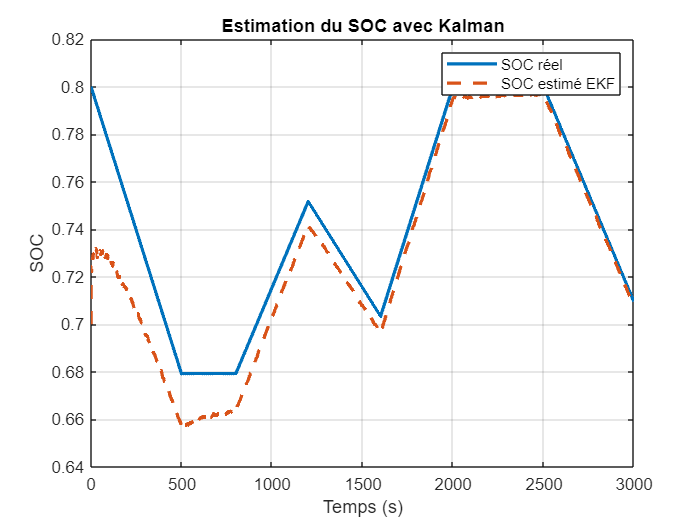

%Sauvegarde des donnees 
save('battery_data.mat', ...
    'data_kalman', ...
    'X_train','Y_train','X_test','Y_test');
%Methode(1): Filtre de Kalman

% Initialisation
N = length(I_bruit);

x_est = zeros(3,N); % [SOC; U1; U2]
x_est(:,1) = [0.7; 0; 0]; % estimation initiale (instant 1)

P = eye(3)*1e-3;   % covariance initiale

% Covariances bruit (valeurs minimes donc plus de confiance pour notre
% modele)
Qk = diag([1e-7, 1e-5, 1e-5]);   % bruit processus    
Rk = 1e-3;                      % bruit mesure

for k = 1:N-1
    
    Ik = I_bruit(k);
    
    %Predictions du filtre
    SOC_k = x_est(1,k);
    U1_k  = x_est(2,k);
    U2_k  = x_est(3,k);
    
    % Matrice A
    A = [1 0 0;
         0 alpha1 0;
         0 0 alpha2];
    
    % Matrice B
    B = [-Ts/Q;
          beta1;
          beta2];
    
    x_pred = A*x_est(:,k) + B*Ik;
    
    P_pred = A*P*A' + Qk;
    
    %% ======================
    %% Mesure (non linéaire)
    %% ======================
    
    Voc = 3.0 + 0.8*x_pred(1);
    
    y_pred = Voc - R0*Ik - x_pred(2) - x_pred(3);
    
    % Jacobienne H
    H = [0.8  -1  -1];
    
    %% ======================
    %% Innovation
    %% ======================
    
    y_meas = Ut_bruit(k);
    
    e = y_meas - y_pred;
    
    S = H*P_pred*H' + Rk;
    
    K = P_pred*H'/S;
    
    %% ======================
    %% Update
    %% ======================
    
    x_est(:,k+1) = x_pred + K*e;
    
    P = (eye(3) - K*H)*P_pred;
end
figure;
plot(t, SOC, 'LineWidth',2); hold on;
plot(t, x_est(1,:), '--', 'LineWidth',2);
legend('SOC réel','SOC estimé EKF');
title('Estimation du SOC avec Kalman');
xlabel('Temps (s)');
ylabel('SOC');
grid on;

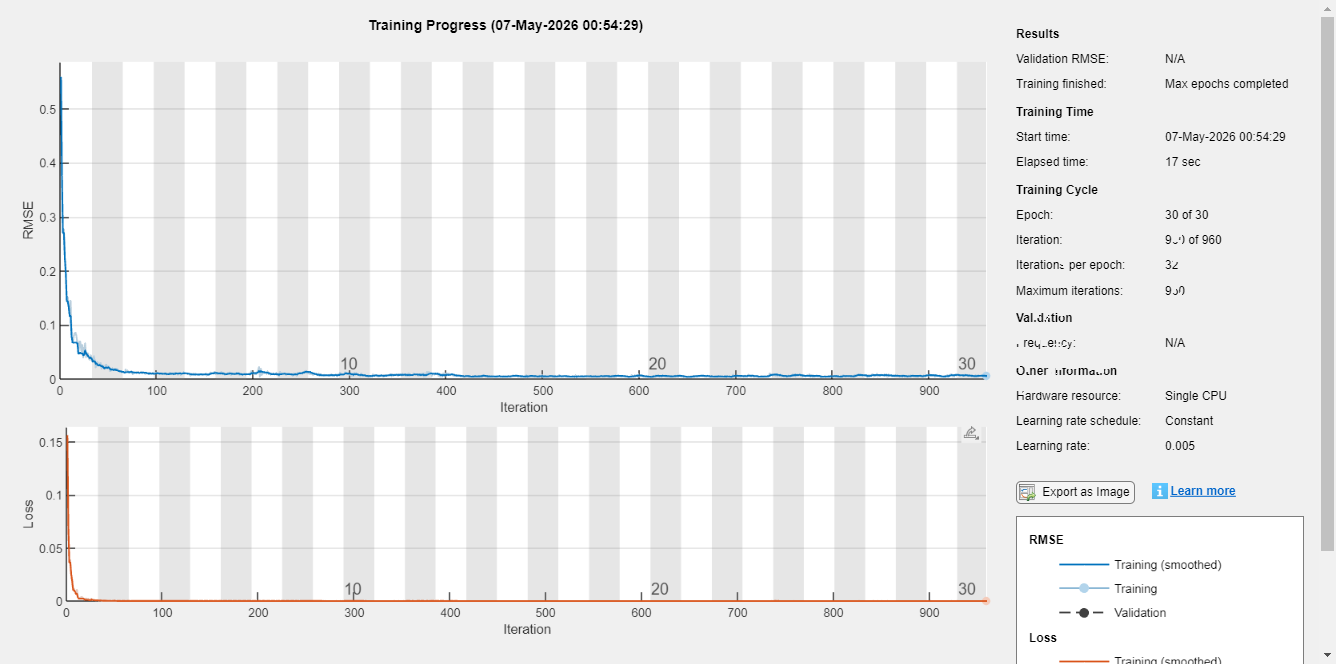

%% ===============================
%% 10. MODELE LSTM
%% ===============================

inputSize = 2;      % [I, Ut]
numHiddenUnits = 50;
numResponses = 1;    % SOC

layers = [ ...
    sequenceInputLayer(inputSize)
    
    lstmLayer(numHiddenUnits, 'OutputMode','last')
    
    fullyConnectedLayer(20)
    reluLayer
    
    fullyConnectedLayer(numResponses)
    regressionLayer];
%% ===============================
%% 11. OPTIONS D'ENTRAINEMENT
%% ===============================

options = trainingOptions('adam', ...
    'MaxEpochs', 30, ...
    'MiniBatchSize', 64, ...
    'InitialLearnRate', 0.005, ...
    'GradientThreshold', 1, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots','training-progress');
%% ===============================
%% 12. TRAINING
%% ===============================

net = trainNetwork(X_train, Y_train, layers, options);

%% ===============================
%% 13. TEST
%% ===============================

YPred = predict(net, X_test);

YTest = Y_test;
rmse = sqrt(mean((YPred - YTest).^2));
disp(['RMSE = ', num2str(rmse)]);

RMSE = 0.036895


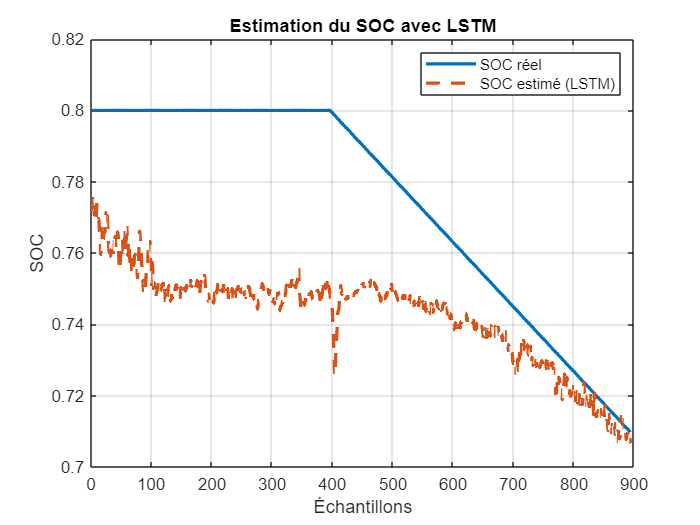

figure;
plot(YTest, 'LineWidth',2); hold on;
plot(YPred, '--', 'LineWidth',2);
legend('SOC réel','SOC estimé (LSTM)');
title('Estimation du SOC avec LSTM');
xlabel('Échantillons');
ylabel('SOC');
grid on;

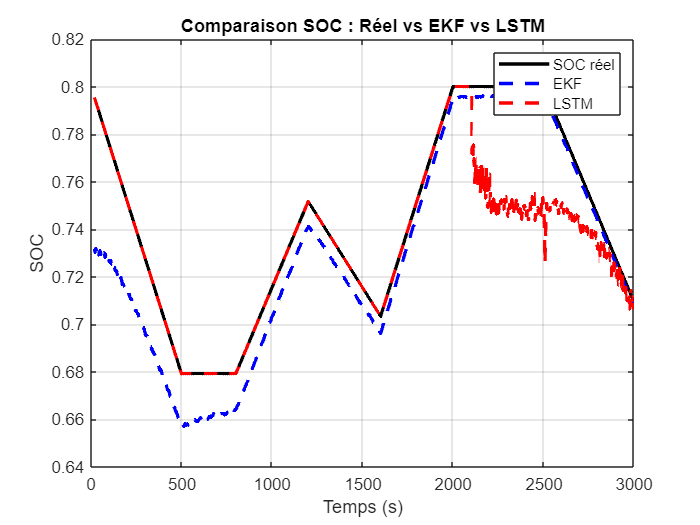

%% ===============================
%% 14. ALIGNEMENT DES DONNEES
%% ===============================

% Temps correspondant au LSTM (car décalage window)
t_lstm = t(window:end-1);

% Reconstruction sortie LSTM complète (train + test)
Y_lstm_full = [Y_train; YPred];

% SOC réel aligné
SOC_lstm = SOC(window:end-1);

% EKF aligné
SOC_ekf_lstm = x_est(1, window:end-1);

%% ===============================
%% 15. COMPARAISON GLOBALE
%% ===============================

figure;

plot(t_lstm, SOC_lstm, 'k', 'LineWidth',2); hold on;
plot(t_lstm, SOC_ekf_lstm, '--b', 'LineWidth',2);
plot(t_lstm, Y_lstm_full, '--r', 'LineWidth',2);

legend('SOC réel','EKF','LSTM');
title('Comparaison SOC : Réel vs EKF vs LSTM');
xlabel('Temps (s)');
ylabel('SOC');
grid on;

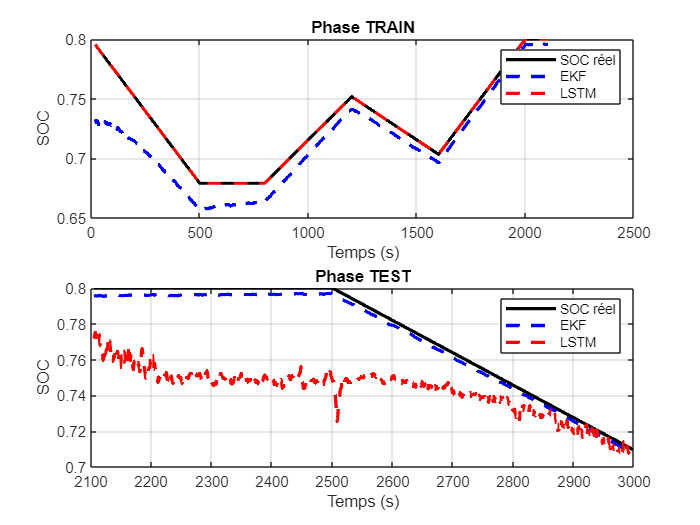


%% ===============================
%% 16. SEPARATION TRAIN / TEST
%% ===============================

figure;

% TRAIN
subplot(2,1,1)
plot(t_lstm(1:idx), SOC_lstm(1:idx), 'k', 'LineWidth',2); hold on;
plot(t_lstm(1:idx), SOC_ekf_lstm(1:idx), '--b', 'LineWidth',2);
plot(t_lstm(1:idx), Y_train, '--r', 'LineWidth',2);

legend('SOC réel','EKF','LSTM');
title('Phase TRAIN');
xlabel('Temps (s)');
ylabel('SOC');
grid on;

% TEST
subplot(2,1,2)
plot(t_lstm(idx+1:end), SOC_lstm(idx+1:end), 'k', 'LineWidth',2); hold on;
plot(t_lstm(idx+1:end), SOC_ekf_lstm(idx+1:end), '--b', 'LineWidth',2);
plot(t_lstm(idx+1:end), YPred, '--r', 'LineWidth',2);

legend('SOC réel','EKF','LSTM');
title('Phase TEST');
xlabel('Temps (s)');
ylabel('SOC');
grid on;


%% ===============================
%% 17. ERREURS COMPARATIVES
%% ===============================

% EKF
rmse_ekf = sqrt(mean((SOC_lstm - SOC_ekf_lstm).^2));

% LSTM (uniquement test)
rmse_lstm = sqrt(mean((Y_test - YPred).^2));

disp(['RMSE EKF  = ', num2str(rmse_ekf)]);

RMSE EKF  = 0.017553


disp(['RMSE LSTM = ', num2str(rmse_lstm)]);

RMSE LSTM = 0.036895


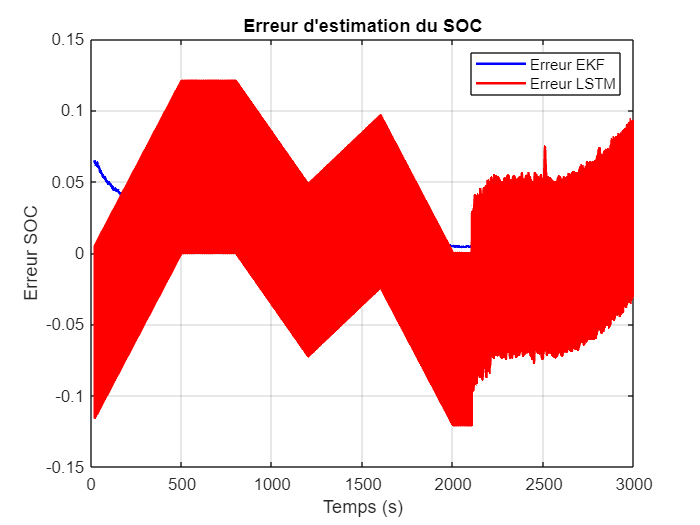


%% ===============================
%% 18. CALCUL DES ERREURS
%% ===============================

% Erreur EKF (sur toute la zone alignée)
err_ekf = SOC_lstm - SOC_ekf_lstm;

% Erreur LSTM (train + test)
err_lstm_full = SOC_lstm - Y_lstm_full;

% Séparation train/test
err_lstm_train = err_lstm_full(1:idx);
err_lstm_test  = err_lstm_full(idx+1:end);

err_ekf_train = err_ekf(1:idx);
err_ekf_test  = err_ekf(idx+1:end);

%% ===============================
%% 19. COURBES D'ERREUR GLOBALES
%% ===============================

figure;

plot(t_lstm, err_ekf, 'b', 'LineWidth',1.5); hold on;
plot(t_lstm, err_lstm_full, 'r', 'LineWidth',1.5);

legend('Erreur EKF','Erreur LSTM');
title('Erreur d''estimation du SOC');
xlabel('Temps (s)');
ylabel('Erreur SOC');
grid on;

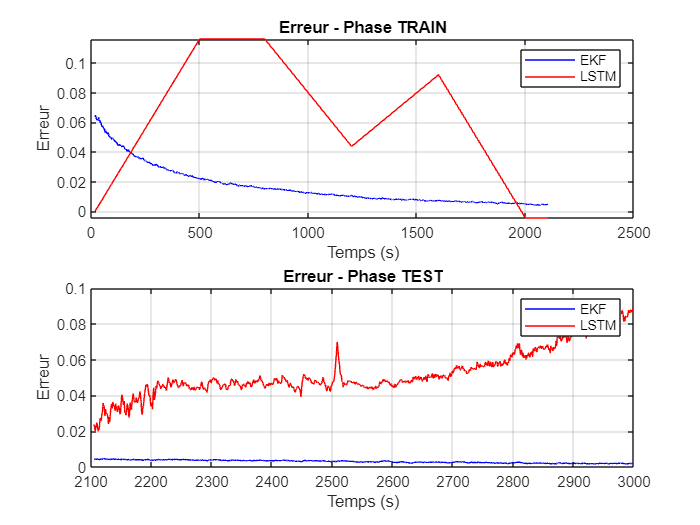


%% ===============================
%% 20. ERREUR TRAIN / TEST
%% ===============================

% Indices propres
idx_train = 1:idx;
idx_test  = idx+1:length(t_lstm);

figure;

% TRAIN
subplot(2,1,1)
plot(t_lstm(idx_train), err_ekf(idx_train), 'b'); hold on;
plot(t_lstm(idx_train), err_lstm_full(idx_train), 'r');

legend('EKF','LSTM');
title('Erreur - Phase TRAIN');
xlabel('Temps (s)');
ylabel('Erreur');
grid on;

% TEST
subplot(2,1,2)
plot(t_lstm(idx_test), err_ekf(idx_test), 'b'); hold on;
plot(t_lstm(idx_test), err_lstm_full(idx_test), 'r');

legend('EKF','LSTM');
title('Erreur - Phase TEST');
xlabel('Temps (s)');
ylabel('Erreur');
grid on;

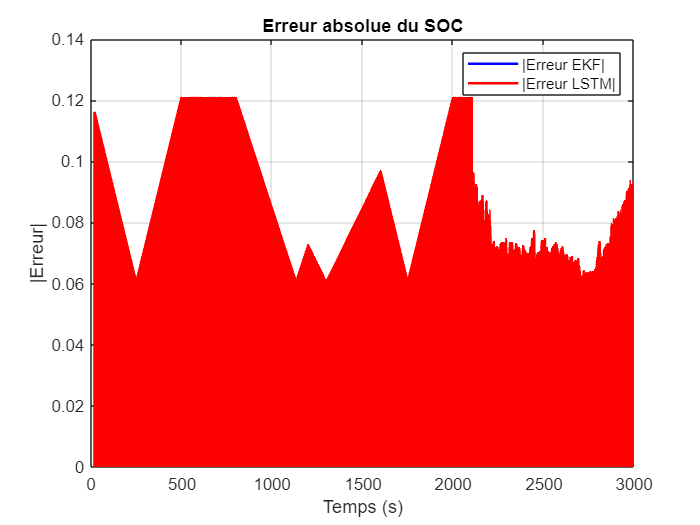

%% ===============================
%% 21. ERREUR ABSOLUE (PLUS LISIBLE)
%% ===============================

figure;

plot(t_lstm, abs(err_ekf), 'b', 'LineWidth',1.5); hold on;
plot(t_lstm, abs(err_lstm_full), 'r', 'LineWidth',1.5);

legend('|Erreur EKF|','|Erreur LSTM|');
title('Erreur absolue du SOC');
xlabel('Temps (s)');
ylabel('|Erreur|');
grid on;


%% ===============================
%% 22. METRIQUES COMPLEMENTAIRES
%% ===============================

% MAE
mae_ekf = mean(abs(err_ekf));
mae_lstm = mean(abs(Y_test - YPred));

disp(['MAE EKF  = ', num2str(mae_ekf)]);

MAE EKF  = 0.012395


disp(['MAE LSTM = ', num2str(mae_lstm)]);

MAE LSTM = 0.032023
